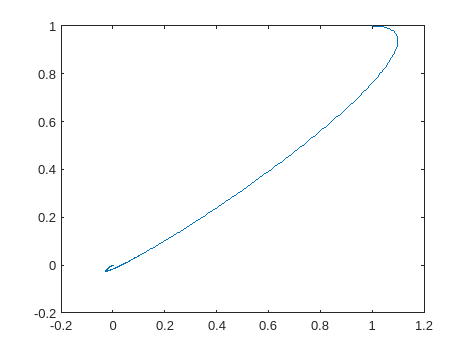

clc;
close all;
clear all;

n= 4;
m= 2;
l= 2;
N= 1000;
x= zeros(n,N);
u= zeros(m,N);
y= zeros(l,N);

A = [0,0,1,0;
    0,0,0,1;
    0,0,0,0;
    0,0,0,0];

B = [0 0;0 0;1 0;0 1];


C = [1,0,0,0;
    0,1,0,0];

D = [];

dt = 0.01;

sys1 = ss(A,B,C,D);
sys2 = c2d(sys1,dt);

At = sys2.A;
Bt = sys2.B;
Ct = sys2.C;

Qx = 1*eye(2);
Qv = 0.1*eye(2);
Q = [Qx,zeros(2,2);
    zeros(2,2),Qv];
R = 0.1*eye(2);

[K,S,e] = dlqr(At,Bt,Q,R,[]);



x0 = [1,1,1,0]';
x(:,1) = x0;
for i=1:N
    u(:,i) = -K*x(:,i);
    x(:,i+1) = At*x(:,i) + Bt*u(:,i);
    y(:,i) = Ct*x(:,i);
end


figure()
plot(x(1,:),x(2,:),'LineWidth',2);

## Add non linear sectors

x= zeros(n,N);
u= zeros(m,N);
yp= zeros(l,N);

x0 = [1,1,1,0]';
cost=[];
costy=[];
c=0;
cy=0;
costyy=[];
cyy=0;
x(:,1) = x0;
for i=1:N
    
    u(:,i) = -K*x(:,i);
    x(:,i+1) = At*x(:,i) + Bt*u(:,i);
    yp(:,i) = phi(Ct*x(:,i));
    c = c+x(:,i)'*x(:,i) + u(:,i)'*u(:,i);
    cost = [cost; c];
    cy =  cy+yp(:,i)'*yp(:,i);% + u(:,i)'*u(:,i);
    costy = [costy; cy];
    
    cyy =  cyy+y(:,i)'*y(:,i);% + u(:,i)'*u(:,i);
    costyy = [costyy; cyy];
end


figure()
plot(x(1,:),x(2,:))

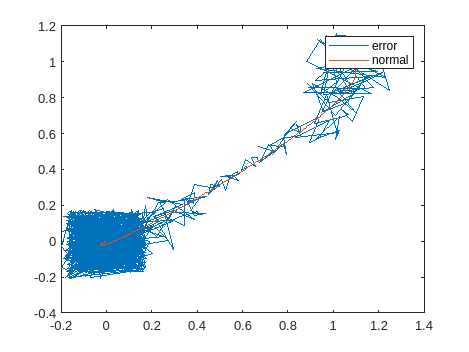



figure()
plot(yp(1,:),yp(2,:));hold on;
plot(y(1,:),y(2,:));
legend('error','normal')

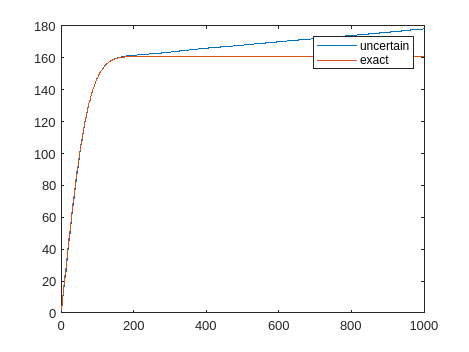



figure()
% plot(cost);hold on;
plot(costy);hold on;
plot(costyy)
legend('uncertain','exact')


output_error = vecnorm(y - yp,2,1);

out = abs(costy - costyy);

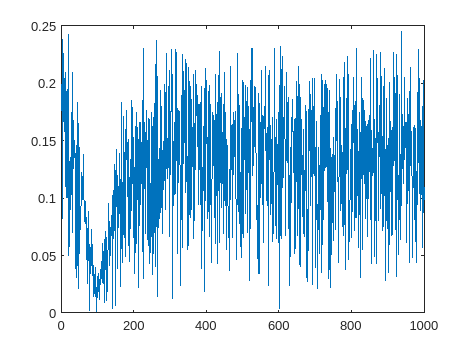

figure()
plot(output_error)

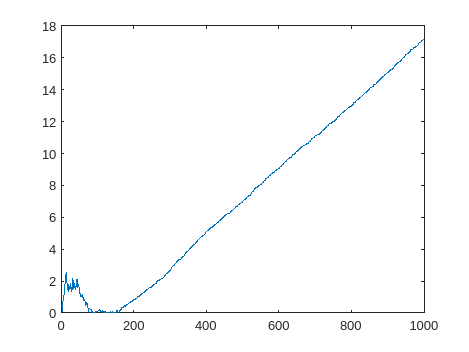


figure()
plot(out)

## Add non linear sectors

x= zeros(n,N); u= zeros(m,N); yp= zeros(l,N);

x0 = [1,1,1,0]; cost=[]; costy=[]; c=0; cy=0; costyy=[]; cyy=0; x(:,1) = x0; for i=1:N

output_error = vecnorm(y - yp,2,1);

out = abs(costy - costyy);

figure() plot(x(1,:),x(2,:))

figure() plot(yp(1,:),yp(2,:));hold on; plot(y(1,:),y(2,:)); legend('error','normal')

u= zeros(m,N);

yp= zeros(l,N);

%
% figure()
% % plot(cost);hold on;
% plot(costy);hold on;
% plot(costyy)
% legend('uncertain','exact')

## Observability nominal

clc;
close all;
eps = 0.01
x_init = x0+eps*[1*eye(n),-1*eye(n),zeros(n,1)];

x_obs=[];
y_obs=[];
for j  = 1:length(x_init)
    xo = zeros(n,N);
    yo = zeros(l,N);
    xo(:,1) = x_init(:,j);
    for i = 1:N
        xo(:,i+1) = At*xo(:,i) + Bt*u(:,i);
        yo(:,i) = Ct*xo(:,i);
    end
    x_obs = [x_obs;xo];
    y_obs = [y_obs;yo];
    
end



figure()
hold on;
for j  = 1:length(x_init)
    plot(x_obs(4*(j-1)+1,:),x_obs(4*(j-1)+2,:))
end
legend()

% obs

Obs = zeros(4,4);
for j = 1:2
    Y=[];
    for i = 1:n
        Y = [Y,(y_obs((i-1)*2+1:(i-1)*2+l,j) - y_obs(l*n+(i-1)*2+1:l*n+(i-1)*2+l,j))];
        
        %           (y_obs((i-1)*2+1:(i-1)*2+l,j) - y_obs(l*n+(i-1)*2+1:l*n+(i-1)*2+l,j))
    end
    Y
    Obs = Obs + Y'*Y;
end
Obs = Obs/(4*eps^2);
eig(Obs)
% Check gramian mapping
z=0;
for i = 1:N
    z = z + (y_obs(1:2,i) - y(:,i))'*(y_obs(1:2,i) - y(:,i));
end
gram_error = z-min(eig(Obs))*norm(x_obs(1:4,:))

## Observability with sector

close all;

x_init = x0+eps*[1*eye(n),-1*eye(n),zeros(n,1)];

x_obs=[];
y_obs=[];
for j  = 1:length(x_init)
    xo = zeros(n,N);
    yo = zeros(l,N);
    xo(:,1) = x_init(:,j);
    for i = 1:N
        xo(:,i+1) = At*xo(:,i) + Bt*u(:,i);
        yo(:,i) = phi(Ct*xo(:,i));
    end
    x_obs = [x_obs;xo];
    y_obs = [y_obs;yo];
    
end



figure()
hold on;
for j  = 1:length(x_init)
    plot(x_obs(4*(j-1)+1,:),x_obs(4*(j-1)+2,:))
end
legend()

## obs

Obsp = zeros(4,4);
for j = 1:N
    Y=[];
    for i = 1:n
        Y = [Y,(y_obs((i-1)*2+1:(i-1)*2+l,j) - y_obs(l*n+(i-1)*2+1:l*n+(i-1)*2+l,j))];
        
        %           (y_obs((i-1)*2+1:(i-1)*2+l,j) - y_obs(l*n+(i-1)*2+1:l*n+(i-1)*2+l,j))
    end
    Obsp = Obsp + Y'*Y/(4*eps^2);
end

eig(Obsp)

## Check gramian mapping

z=0;
for i = 1:N
    z = z + (y_obs(1:2,i) - y(:,i))'*(y_obs(1:2,i) - y(:,i));
end
gram_error = z-min(eig(Obs))*norm(x_obs(1:4,:));

## Output based control?

x= zeros(n,N);
uy= zeros(m,N);
yp= zeros(l,N);

Ky = 0.5*eye(2);
Kyd = 1*eye(2);
x0 = [1,1,1,0]';
x(:,1) = x0;
ypre = yp(:,1)
for i=1:N
    
    yp(:,i) = Ct*x(:,i);
    err = (yp(:,i) - ypre)/dt
    uy(:,i) = -Ky*yp(:,i) - Kyd*err;
    x(:,i+1) = At*x(:,i) + Bt*uy(:,i);
    ypre = yp(:,i);
end

figure()
plot(x(1,:),x(2,:))

figure()
plot(x(1,:));hold on;
plot(x(2,:));

## Observability nominal

clc;
close all;
eps = 0.001;
x_init = x0+eps*[1*eye(n),-1*eye(n),zeros(n,1)];

x_obs=[];
yy_obs=[];
for j  = 1:length(x_init)
    xo = zeros(n,N);
    yo = zeros(l,N);
    xo(:,1) = x_init(:,j);
    for i = 1:N
        xo(:,i+1) = At*xo(:,i) + Bt*uy(:,i);
        yo(:,i) = Ct*xo(:,i);
    end
    x_obs = [x_obs;xo];
    yy_obs = [yy_obs;yo];
    
end



figure()
hold on;
for j  = 1:length(x_init)
    plot(x_obs(4*(j-1)+1,:),x_obs(4*(j-1)+2,:))
end
legend()

% obs

Obsy = zeros(4,4);
for j = 1:2
    Y=[];
    for i = 1:n
        Y = [Y,(yy_obs((i-1)*2+1:(i-1)*2+l,j) - yy_obs(l*n+(i-1)*2+1:l*n+(i-1)*2+l,j))];
        
        %           (y_obs((i-1)*2+1:(i-1)*2+l,j) - y_obs(l*n+(i-1)*2+1:l*n+(i-1)*2+l,j))
    end
    Y
    Obsy = Obsy + Y'*Y;
end
Obsy = Obsy/(4*eps^2);
eig(Obsy)


% Check gramian mapping
z=0;
for i = 1:N
    z = z + (y_obs(1:2,i) - yp(:,i))'*(y_obs(1:2,i) - yp(:,i));
end
gram_error = z-min(eig(Obsy))*norm(x_obs(1:4,:))

## Output based control sector based

x= zeros(n,N);
uy= zeros(m,N);
yp= zeros(l,N);

Ky = 0.5*eye(2);
Kyd = 1*eye(2);
x0 = [1,1,1,0]';
x(:,1) = x0;
ypre = yp(:,1)
for i=1:N
    
    yp(:,i) = phi(Ct*x(:,i));
    err = (yp(:,i) - ypre)/dt
    uy(:,i) = -Ky*yp(:,i) - Kyd*err;
    x(:,i+1) = At*x(:,i) + Bt*uy(:,i);
    ypre = yp(:,i);
end

figure()
plot(x(1,:),x(2,:))

figure()
plot(x(1,:));hold on;
plot(x(2,:));

## Observability nominal

clc;
close all;
eps = 0.001;
x_init = x0+eps*[1*eye(n),-1*eye(n),zeros(n,1)];

x_obs=[];
yy_obs=[];
for j  = 1:length(x_init)
    xo = zeros(n,N);
    yo = zeros(l,N);
    xo(:,1) = x_init(:,j);
    for i = 1:N
        xo(:,i+1) = At*xo(:,i) + Bt*uy(:,i);
        yo(:,i) = phi(Ct*x(:,i));
    end
    x_obs = [x_obs;xo];
    yy_obs = [yy_obs;yo];
    
end



figure()
hold on;
for j  = 1:length(x_init)
    plot(x_obs(4*(j-1)+1,:),x_obs(4*(j-1)+2,:))
end
legend()

% obs

Obsy = zeros(4,4);
for j = 1:2
    Y=[];
    for i = 1:n
        Y = [Y,(yy_obs((i-1)*2+1:(i-1)*2+l,j) - yy_obs(l*n+(i-1)*2+1:l*n+(i-1)*2+l,j))];
        
        %           (y_obs((i-1)*2+1:(i-1)*2+l,j) - y_obs(l*n+(i-1)*2+1:l*n+(i-1)*2+l,j))
    end
    Y
    Obsy = Obsy + Y'*Y;
end
Obsy = Obsy/(4*eps^2);
eig(Obsy)


% Check gramian mapping
z=0;
for i = 1:N
    z = z + (y_obs(1:2,i) - yp(:,i))'*(y_obs(1:2,i) - yp(:,i));
end
gram_error = z-min(eig(Obsy))*norm(x_obs(1:4,1) - x0)

gram_error = z-norm(sqrt(Obsy)*(x_obs(1:4,1)) - x0)

gram_error = z - (x_obs(1:4,1) - x0)'*Obsy*(x_obs(1:4,1) - x0)

function y = phi(x)
y = x + norm(x-[0.5;0.5])*0.5*(0.5-rand(size(x)));
end